# Structure of Ships

## Topics

- `struct` and `string` data types

- String formatting

## Create a small structure for testing.

Using Wikipedia's list of [current US Navy ships](https://en.wikipedia.org/wiki/List_of_current_ships_of_the_United_States_Navy), Create a structure array named `ships`  and store at least four entries with the following field names and values (note that there are a few different ways to create and populate a [structure array](https://www.mathworks.com/help/matlab/ref/struct.html)):

- `name`: the Ship name as a string

- `hull`: Hull number as a string

- `class`: Name of the class as a string

- `type`: The listed type as a string

- `year`: Year of commission as a number

clear ships

% I picked the first four from the list.  
% Illustrating two alternative ways to initialize elements.
ships(1).name = "USS Abraham Lincoln";
ships(1).hull = "CVN-72";
ships(1).class = "Nimitz";
ships(1).type = "Aircraft carrier";
ships(1).year = 1989;
ships(2) = struct("name", "USS Alabama", "hull", "SSBN-731", ...
    "class", "Ohio", "type", "Ballistic missile submarine", "year", 1985);
ships(3) = struct("name", "USS Alaska", "hull", "SSBN-732", ...
    "class", "Ohio", "type", "Ballistic missile submarine", "year", 1986);
ships(4) = struct("name", "USS Albany", "hull", "SSN-753", ...
    "class", "Los Angeles", "type", "Attack submarine", "year", 1990);

ships

ships = 1×4 struct array with fields:
    name
    hull
    class
    type
    year


When you display the contents of the ships variable (of type struct) you should see something like this...

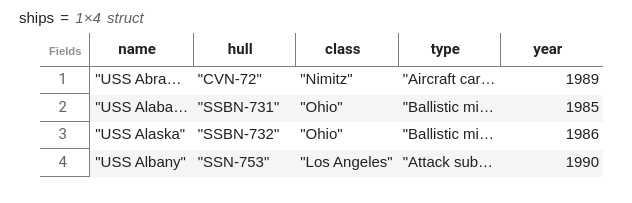

## Finding ships by year

Write a function named `print_ships_by_year` to report all the ships commissioned on-or-after a user-provided year.

Input Arguments:

- structure with the fields defined in above.

- threshold year as a number (aka, double) 

Return Values: None

Operation: Print formatted text to the screen of the ship name and year in descending order by year for vessels commissioned on or after the user-provided year.  The formatting is illustrated below.

Example:

If we our structure contains the first four ships from the wikipedia page and the year is 1986, we would expect the following behavior of the function:

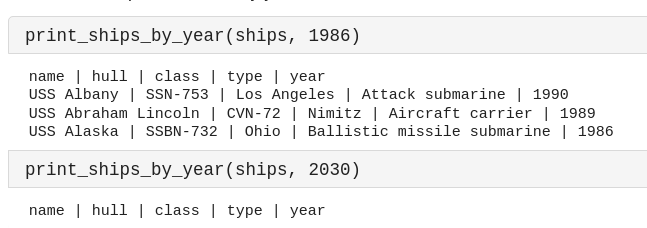

function [] = print_ships_by_year(ships, year)

name | hull | class | type | year 
USS Albany | SSN-753 | Los Angeles | Attack submarine | 1990 
USS Abraham Lincoln | CVN-72 | Nimitz | Aircraft carrier | 1989 
USS Alaska | SSBN-732 | Ohio | Ballistic missile submarine | 1986 


    % Extract a subset by year.

name | hull | class | type | year 


    years = [ships.year];
    subset = ships(find(years >= year));

    % Sort the years array and return the indexes for the sort
    % Default behavior is ascending, but we want descending.
    years_subset = [subset.year];
    [years_sorted, sort_indx] = sort(years_subset, 'descend');
    % Use the indexes to apply the sort to the struct
    subset_sorted = subset(sort_indx);
    
    % Print the output
    fprintf("name | hull | class | type | year \n");
    for ii = 1:length(subset_sorted)
        fprintf("%s | %s | %s | %s | %d \n", subset_sorted(ii).name, subset_sorted(ii).hull, ...
            subset_sorted(ii).class, subset_sorted(ii).type, subset_sorted(ii).year);
    end
end


Write a few simple tests to verify your function.

print_ships_by_year(ships, 1986)
print_ships_by_year(ships, 2030)